country='china';

data = select_and_normalize(country,false);
tr = data.tr;
te = data.te;
y_tr = data.y_tr;
y_te = data.y_te;
col_names = data.col_names;
if strcmp('taiwan',country)
    [tr,col_names_exp] = expand(tr,2,true,false,col_names);
    [te,~]             = expand(te,2,true,false,col_names);
    cols = [1,2,3,5,6,7,10];
    tr = tr(:,cols);
    te = te(:,cols); 
    col_names = col_names_exp(cols);
end

Select the important columns among the expansion

scores = [] ;
best_score  = -100;
best_lambda = 0 ;
for lambda=[0,logspace(-2,3,200)]
    model = ols(tr,y_tr,'ridge',lambda);
    beta = model.beta;
    test_score = test_model(beta,te,y_te);
    R2 = test_score.R2;
    scores = [scores,R2];
    if R2 > best_score
        best_score = R2;
        best_lambda = lambda;
    end
end
best_lambda

best_lambda = 1.4481

best_score

best_score = -0.2206

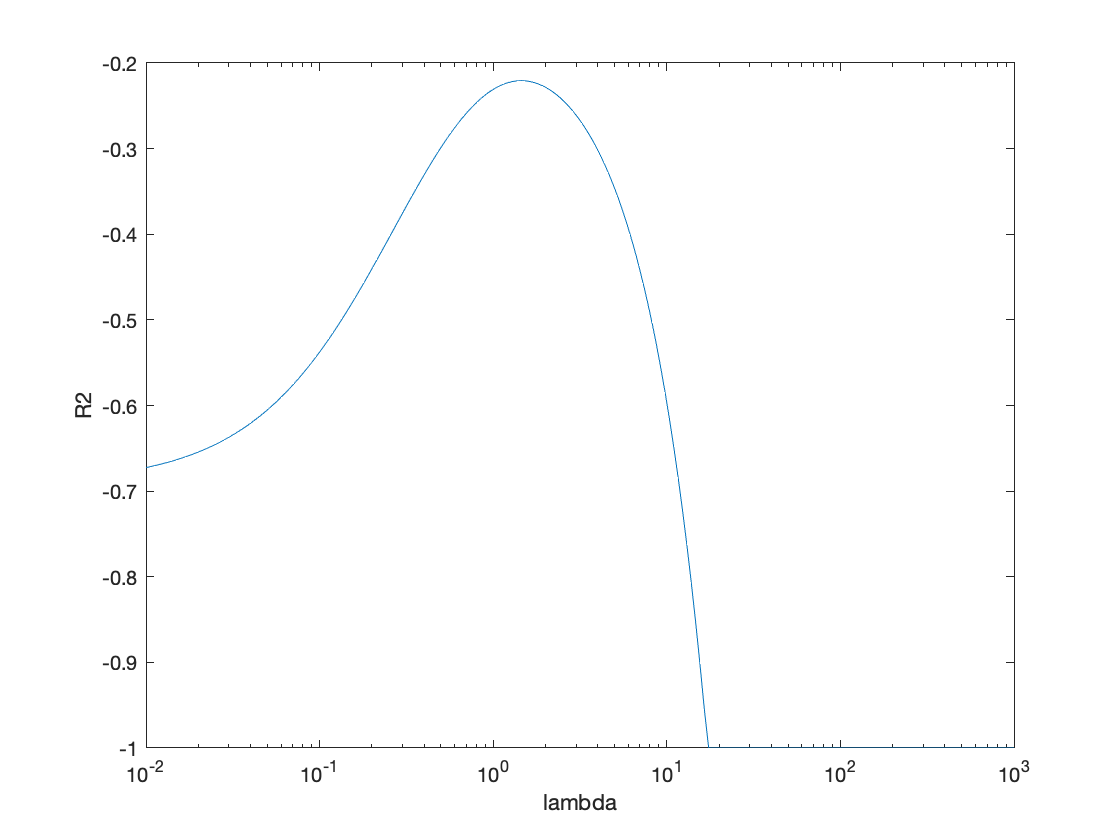

figure
semilogx([0,logspace(-2,3,200)],max(scores,-1))
ylabel({'R2'});
xlabel({'lambda'});